## Parse the data from the specs

clear
structure = SpecParser("global_specs.txt")

structure = struct with fields:
               task_type: 'wav'
            wav_filename: 'inputsignal.wav'
                  wav_fs: 10000
             signal_type: 'rect'
                      fs: 20000
       signal_duration_s: 4
           periodicity_s: 0.5000
             frequencies: [100 200 300 400]
     spectral_resolution: 1
             window_type: 'rect'
            stft_overlap: 50
               filtering: 'iir'
            filter_order: 4
    approximation_method: 'butterworth'
             filter_type: 'bp'
       cut_off_frequency: [1000 4000]
              x_lim_time: 0.0100
         y_lim_amplitude: 1
             x_axis_type: 'lin'
             y_axis_type: 'log'
         x_lim_frequency: '200'
                y_lim_au: 200


## Signal selection, .wav read, resample

task_type = structure.task_type % Determine whether to generate or read .wav

task_type = 'wav'


if (strcmp(task_type, 'wav'))

    dir_name = pwd; % Directory where the file is
    f_name = structure.wav_filename; % File name
    [y, fs_o] = audioread(fullfile(dir_name, f_name));% Read the audio file
    y=y(:,1); % If it's stereo remove one channel

    % Resample with correct frequency
    fs = structure.wav_fs; % Required sampling frequency
    if (fs_o~=fs) % if original fs is not equal to required fs
        signal = resample(y, fs, fs_o); % Resample from fs_o to fs_y
    end

    t = 0:1/fs:length(signal)/fs-1/fs; % Time vector for y
    t=t(:);

    %saving data if needed
    save_data({t, signal},{'Time','Amplitude'}, 'audio_signal');
end

## Generate signal

if (strcmp(task_type, 'generate'))

    type = structure.signal_type; % Signal type
    fs = structure.fs; % Signal sampling frequency
    duration = structure.signal_duration_s; % Extract duration of signal
    frequencies = structure.frequencies; % Frequencies in the signal
    t = 0:1/fs:duration-1/fs; % Time vector
    signal = zeros(1,length(t)); % Initialize signal with zeros

    if strcmp(type, 'rect') % Check if signal type is a rectangle
       periodicity = structure.periodicity_s % Extract periodicity for if the signal is rect
        % We use the sin function to generate required periodicity and sign to
        % transform into a rectangular wave
        signal = sign(sin(2*pi/periodicity*t)); %Construct the signal
    end

    if strcmp(type, 'tone') % Check if signal type is a tone
        for i = 1:length(frequencies) % Itterates for the amount of frequencies
            signal = signal+cos(2*pi*frequencies(i)*t); %Construct the signal
        end
    end

    if strcmp(type, 'tone-complex') % Check if signal type is a complex tone
        for i = 1:length(frequencies) % Itterates for the amount of frequencies
            phase = rand()*2*pi; % Generates phase in the range 0 to 2pi
            signal = signal+cos(2*pi*frequencies(i)*t+phase); %Consstruct the signal
        end
    end

    if strcmp(type, 'noise') % Is signal type noise?
        signal = rand(1,fs*duration)-0.5; % Generates random values from -0.5 to 0.5 for each sample
    end

    % Save the generated signal
    save_data({t, signal},{'Time','Amplitude'}, 'generated_signal');

end

## DFT

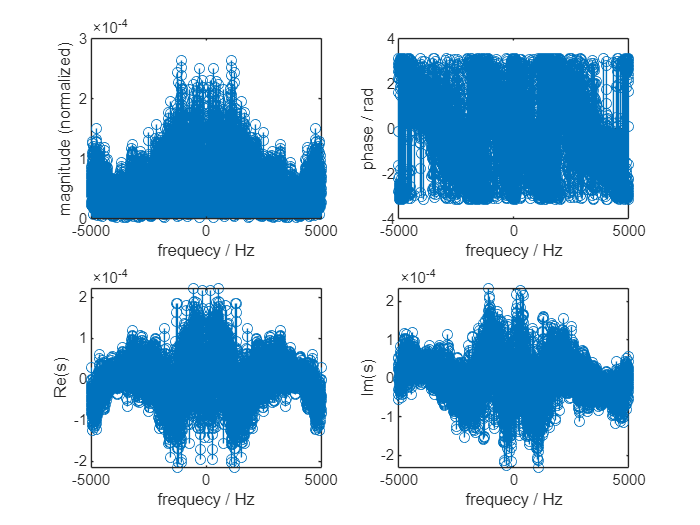

% Make spectrum takes in the signal, its fs, required spectral resolution and gives 
% NORMALIZED spectrum and a frequency vector. 
% Required spectral resolution is realized by resampling the transformed
% signal to the required resolution. the function resample() only takes in
% integers for p and q meaning that 1/resample has to be an integer.
% Resolution could be [0.2,0.5,1]

spectral_resolution = structure.spectral_resolution; % Required spectral resolution
[Y, f] = make_spectrum(signal, fs,spectral_resolution); % DFT function


% Save spectrum and frequency vector
%save_data({f, abs(Y), real(Y), imag(Y)},{'Frequency', 'Magnitude', 'Real', 'Imaginary'},'dft_signal');

## **STFT**

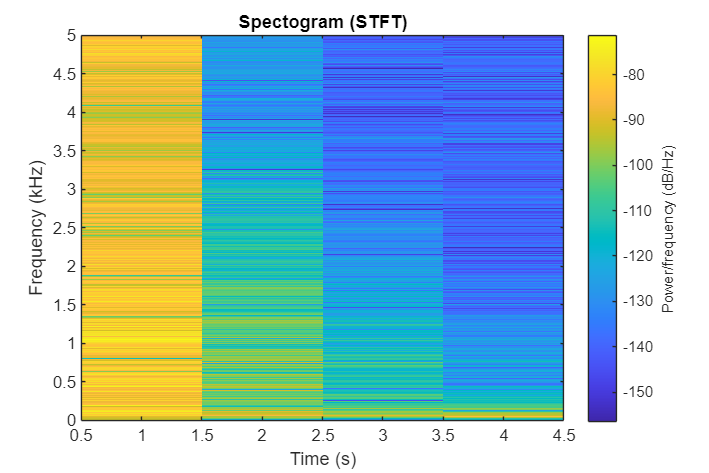

overlap = structure.stft_overlap; % Overlap for stft in percent
window_type = structure.window_type; % Required window type
figure()

if strcmp(window_type, 'hann')
    N = 4*fs/spectral_resolution; % Calculate window length in samples
    w = hann(round(N)); % Generate required window
    overlap_n = round(overlap/100*N); % Overlap in samples
    spectrogram(signal,w,overlap_n,[],fs,'yaxis')
end

if strcmp(window_type, 'hamming')
    N = 4*fs/spectral_resolution;
    w = hamming(round(N)); % Generate required window
    overlap_n = round(overlap/100*N); % Overlap in samples
    spectrogram(signal,w,overlap_n,[],fs,'yaxis')
end

if strcmp(window_type, 'rect')
    N = 2*fs/spectral_resolution;
    w = rectwin(round(N)); % Generate required window
    overlap_n = round(overlap/100*N); % Overlap in samples
    spectrogram(signal,w,overlap_n,[],fs,'yaxis')
end
title("Spectogram (STFT)")
save_plot('STFT');

## Filter design

% use the filter parameters from specs
filtering = structure.filtering;
approximation_method = structure.approximation_method;
filter_type = structure.filter_type;
filter_order = structure.filter_order;
cutoff_freqs_norm = structure.cut_off_frequency / (fs/2); % normalised cut-off frequencies

% design the IIR filter
[b_iir, a_iir] = designIIRfilter(filter_type, approximation_method, filter_order, cutoff_freqs_norm);

% check for desired filter type and create one accordingly
if strcmp(filtering, 'IIR')
    % use the IIR filter coefficients directly
    final_filter = struct('b', b_iir, 'a', a_iir);
else
    % transform IIR into FIR 
    [b_fir, a_fir] = iir_to_fir(b_iir, a_iir, filter_order);
    % use FIR filter coefficients
    final_filter = struct('b', b_fir, 'a', a_fir);
end

## Filtering

% apply the filter to the data
if strcmp(filtering, 'iir')
    filtered_data_signal = filter(b_iir, a_iir, signal);
    disp(['Filter Coefficients (b): ', num2str(b_iir)]);
    disp(['Filter Coefficients (a): ', num2str(a_iir)]);
    b = b_iir;
    a = a_iir;
elseif strcmp (filtering, 'fir')
    disp('FIR Filter Coefficients (b):');
    disp(b_fir.'); %displayed as row 
    disp(['Filter Coefficients (a): ', num2str(a_fir)]);
    filtered_data_signal = filter(b_fir, a_fir, signal);
    b = b_fir;
    a = a_fir;
end

Filter Coefficients (b): 0.16718           0    -0.66872           0      1.0031           0    -0.66872           0     0.16718


Filter Coefficients (a): 1 -1.3323e-15     -0.7821 -3.8858e-16     0.67998 -3.3307e-16    -0.18268  2.7062e-16    0.030119


% saving the coefficents
save_coefficients(a, b);
%save_data({t, filtered_data_signal},{'Time','Filtered Amplitude'}, 'filtered_signal');

## Plotting

Read parameters from spec sheet

% Time plots
x_lim = structure.x_lim_time;
y_lim = structure.y_lim_amplitude;

% Frequency plots
x_axis_type = structure.x_axis_type;
y_axis_type = structure.y_axis_type;
x_lim_freq = structure.x_lim_frequency; 
y_lim_au = structure.y_lim_au;

**1) Time signals: Original + Filtered**

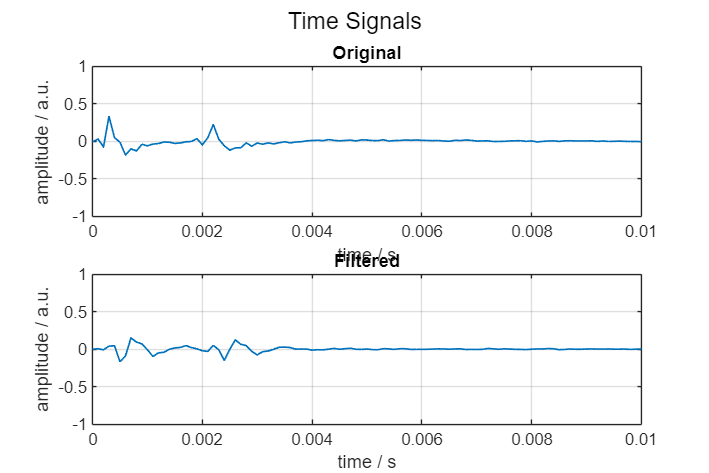

figure()
sgtitle('Time Signals','FontSize', 14) % Subplot title

subplot(2,1,1)
plot(t,signal,'linewidth',1);
plot_specs(x_lim, y_lim, 'time / s', 'amplitude / a.u.', "Original","noleg")

subplot(2,1,2)
plot(t,filtered_data_signal,'linewidth',1);
plot_specs(x_lim, y_lim, 'time / s', 'amplitude / a.u.', "Filtered","noleg")

% Saving the plot
save_plot('filtered_and_original_signal');

**2) Magnitude/phase of Original Signal**

figure
sgtitle( 'Magnitude and Phase of signal' ,'FontSize', 14)
% Only positive frequencies
fposit=f(f>=0); % length(f)/2 +1 (DC offset)
Yposit=Y(f>=0);
magnitude=abs(Yposit);
phase=angle(Yposit);

% Magnitude diagram ------------------------
    % Specifications
if isnan(str2double(x_lim_freq)) && (x_lim_freq == 'nyquist')  % Enters if variable isn't a number
    x_lim_freq=fs/2; %If nyquist, then fs/2"
else
    x_lim_freq=str2double(x_lim_freq)
end

x_lim_freq = 200

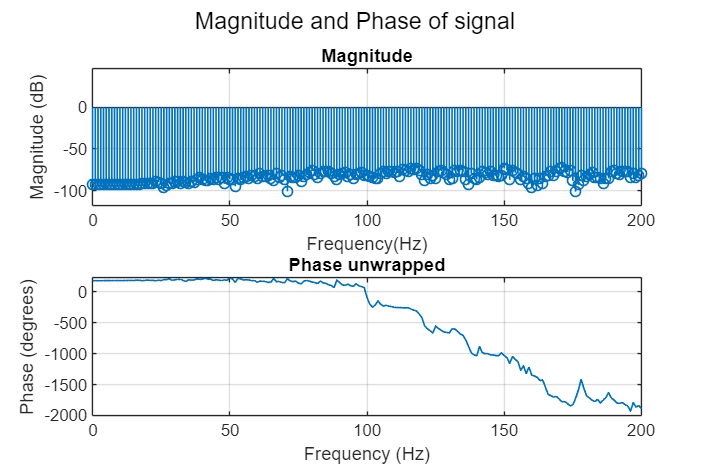


subplot(2, 1, 1);
ax = gca;
if y_axis_type == 'lin' % Frequency as a.u.
    if x_axis_type == 'lin' 
        stem(fposit, magnitude,'linewidth',1);
        ax.XLim = [0 x_lim_freq];
        xlabel('Frequency(Hz)');
    else
        % not using semilogx because preferred to used stem.
        stem(log10(fposit), magnitude,'linewidth',1)
        ax.XLim = [0 log10(x_lim_freq)];
        xlabel('Frequency (log_{10}(Hz)))');
    end
    ylabel('Magnitude (a.u.)')
    ax.YLim = [0 y_lim_au];
else % Frequency as decibels.
    if x_axis_type == 'lin' 
        stem(fposit, 20*log10(magnitude),'linewidth',1);
        ax.XLim = [0 x_lim_freq];
        xlabel('Frequency(Hz)');
    else
        stem(log10(fposit), 20*log10(magnitude),'linewidth',1); % not using semilogx, preferred to used stem.
        ax.XLim = [0 log10(x_lim_freq)];
        xlabel('Frequency (20log_{10}(Hz)))');
    end
    ylabel('Magnitude (dB)')
    ax.YLim = [min([20*log10(y_lim_au);20*log10(magnitude);0]), max([20*log10(y_lim_au);0;20*log10(magnitude)]) ];
end
set(ax,'FontSize',10)
grid()
title('Magnitude')


% Phase diagram ------------------------
subplot(2, 1, 2);
ax=gca;
plot(fposit, unwrap(phase)*180/pi,'linewidth',1);
title('Phase unwrapped');
ax.XLim = [0 x_lim_freq];
set(ax,'Fontsize',10) 
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid()
set(gca,'Fontsize',10) % xtick could be added in specs and set here.
save_plot('magnitude_phase');

**3) Real/Imaginary parts of Original Signal**

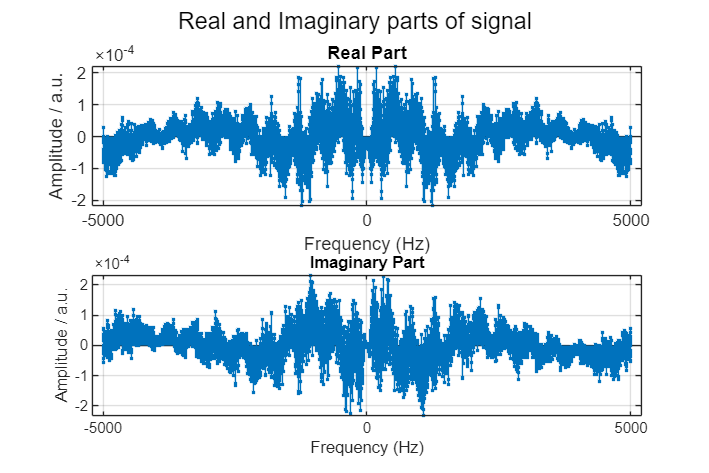

figure()
sgtitle('Real and Imaginary parts of signal','FontSize', 14)
% Plot the real and imaginary parts of the original and filtered signals
subplot(2, 1, 1);
stem(f,real(Y),'.');
xlabel('Frequency (Hz)')
%ylim([-y_lim_au,y_lim_au])
ylabel('Amplitude / a.u.')
title("Real Part")
grid()
set(gca,'Fontsize',10) % xticks could be added
subplot(2, 1, 2);
stem(f,imag(Y),'.');
xlabel('Frequency (Hz)')
%ylim([-y_lim_au,y_lim_au])
ylabel('Amplitude / a.u.')
title("Imaginary Part")
grid()

% Save to plot
save_plot('real_imaginary');

**4) Pole/zero diagram**

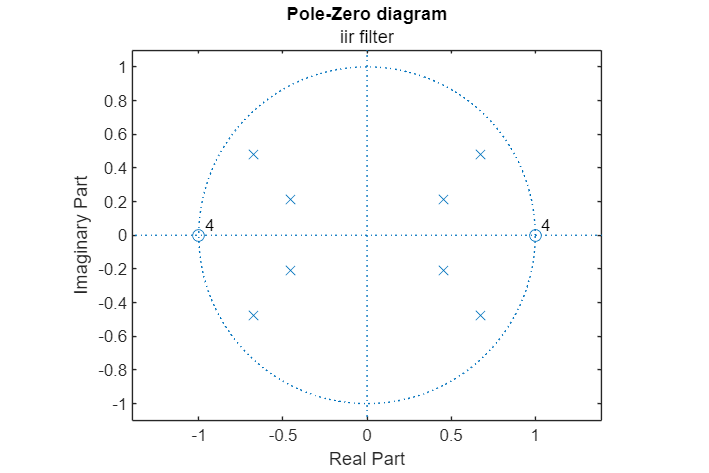

Fpoles = roots(a);
Fzeros = roots(b);

figure()
zplane(Fzeros, Fpoles);
title('Pole-Zero diagram');
subtitle([structure.filtering ' filter']);
save_plot('pole_zero');

**5) Filter transfer function  **

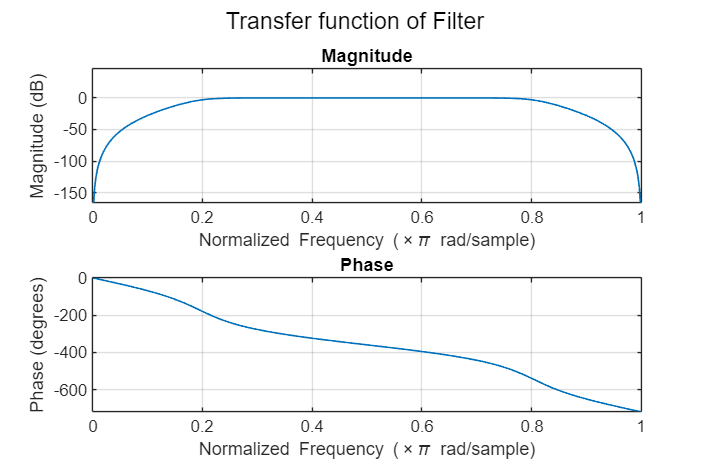

[h,w] = freqz(b,a);
figure()
sgtitle('Transfer function of Filter','FontSize', 14)
subplot(2,1,1)
ax = gca;

% Magnitude response in decibels.

if y_axis_type == 'lin' % Frequency as a.u.
    plot(w/pi,abs(h),'linewidth',1) % normalized frequency, freq response in dB scale
    ylabel('Magnitude (a.u.)')
    ax.YLim = [0 y_lim_au];
else % Frequency as decibels.
    plot(w/pi, 20*log10(abs(h)),'linewidth',1); % not using semilogx, preferred to used stem.
    xlabel('Frequency (20log_{10}(Hz)))');
    ylabel('Magnitude (dB)')
    ax.YLim = [min([20*log10(y_lim_au);20*log10(abs(h));0]), max([20*log10(y_lim_au);20*log10(abs(h));0])];
end
ax.XTick = 0:.2:1; % could delete
ax.XLim = [0 1]; % normalized freq
xlabel('Normalized Frequency (\times\pi rad/sample)');
set(ax,'FontSize',10)
grid()
title('Magnitude')

% Phase diagram ------------------------
subplot(2,1,2) % Automatic axis here
ax=gca;
plot(w/pi, unwrap(angle(h))*180/pi,'linewidth',1);
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Phase (degrees)')
set(ax,'Fontsize',10)
grid()
title("Phase")
save_plot('transfer_function');